# MainClassification

## Settings

addpath('functions')

## Organize dataset

load('DatasetENEEB.mat')

nFeatures = 40;

dataTrain=Run1(:,1:40);
labelsTrain=Run1(:,41);

dataTest=[Run2(:,1:40) ; Run3(:,1:40)];
labelsTest=[Run2(:,41) ; Run3(:,41)];

featNames = cellstr(string([1:20 1:20]));

clear Run2 Run3


## Feature Selection

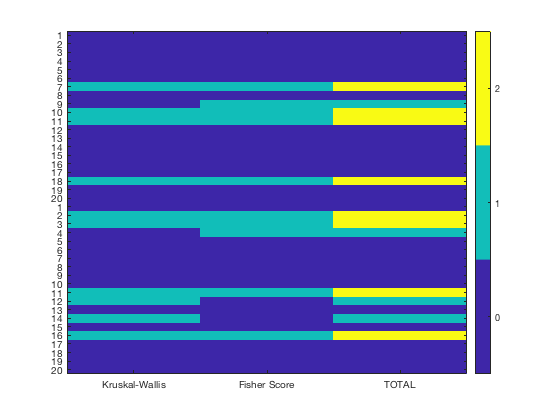

nTopFeatures = 10;

% Feature Selection using two criteria - Fisher score,  Kruskal Wallis     
[ ~ , ~ , fs1] = FS_kruskal( dataTrain , labelsTrain , featNames , nTopFeatures );
[ ~ , ~ , fs2] = FS_fisher( dataTrain , labelsTrain , featNames , nTopFeatures );

% Plot intersection of feature selection methods
plotFSfig(fs1,fs2,nFeatures,featNames)

## Train model

[trainedClassifier, validationAccuracy] = trainSVMClassifier(Run1)

trainedClassifier = struct with fields:
           predictFcn: @(x)svmPredictFcn(predictorExtractionFcn(x))
    ClassificationSVM: [1×1 ClassificationECOC]
                About: 'This struct is a trained model exported from Classification Learner R2018b.'
         HowToPredict: 'To make predictions on a new predictor column matrix, X, use: ↵  yfit = c.predictFcn(X) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵X must contain exactly 40 columns because this model was trained using 40 predictors. ↵X must contain only predictor columns in exactly the same order and format as your training ↵data. Do not include the response column or any columns you did not import into the app. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy = 0.9844

## Interface

% Load images
I1 = imread('images/hands_left-60_right-60.png');
I2 = imread('images/hands_left-100_right-60.png');
I3 = imread('images/hands_left-60_right-100.png');

% Start image
figure('name','interface','position',[100 100 1000 600])

for jj = 1:size(dataTest,1)
    
    yfit = trainedClassifier.predictFcn(dataTest(jj,:))
    
    switch yfit
        case 0
            image(I1)
        case 1
            image(I2)
        case 2
            image(I3)
    end
    
    pause(0.25) % adjust to refresh rate?
    
end
